clear all; close all; clc;

% Font settings
font_name = 'Times'; % Font name
font_size = 12; % Font size

**Import data**

num_markers = 8;

% Import data from static1 (relaxed upper-limb)
data_static1 = readmatrix('static2.csv');
frame_static1 = data_static1(4:end, 1); 
coordinate_mm_static1 = data_static1(4:end, 3:end);

% Conversion from mm to m
coordinate_m_static1 = coordinate_mm_static1 / 1000;

**Rigid Body Tree - Design**

% RIGID BODY TREE design
UpperLimbBiomechanicalModel = rigidBodyTree;
UpperLimbBiomechanicalModel.Gravity=[0 0 -9.81];

coords_STRN = coordinate_m_static1(:,1:3);
coords_SHO = coordinate_m_static1(:,4:6);

coords_ELB1 = coordinate_m_static1(:,7:9);
coords_ELB2 = coordinate_m_static1(:,10:12);
coords_ELB = ( coords_ELB1 + coords_ELB2 )/2;

coords_WRIST1 = coordinate_m_static1(:,19:21);
coords_WRIST2 = coordinate_m_static1(:,22:24);
coords_WRIST = ( coords_WRIST1 + coords_WRIST2 )/2;

% Mean of coordinates to determine the origin of the RFs for each joint
mean_STRN = mean(coords_STRN);
mean_SHO = mean(coords_SHO);
mean_ELB = mean(coords_ELB);
mean_WRIST = mean(coords_WRIST);

**Base: STRN**

% Translation of the RF's origin from STRN to SHO
translation_STRN2STRN = mean_STRN - mean_STRN;

% Transformation matrix 4x4
T_STRN2STRN = trvec2tform(translation_STRN2STRN);

bodybase = rigidBody('base');
basename = UpperLimbBiomechanicalModel.BaseName;

STRN = rigidBody('STRN');
jnt1 = rigidBodyJoint('jnt1','fixed');
setFixedTransform(jnt1,T_STRN2STRN);
STRN.Joint = jnt1;

addBody(UpperLimbBiomechanicalModel,STRN,basename);

**Joint1: SHO**

translation_STRN2SHO = mean_SHO - mean_STRN;

T_STRN2SHO = trvec2tform(translation_STRN2SHO);

SHO = rigidBody('SHO');
jnt2 = rigidBodyJoint('jnt2','revolute');
setFixedTransform(jnt2,T_STRN2SHO);
SHO.Joint = jnt2;

addBody(UpperLimbBiomechanicalModel,SHO,'STRN');

**Joint2: ELB**

translation_SHO2ELB = mean_ELB - mean_SHO;

T_SHO2ELB = trvec2tform(translation_SHO2ELB);

ELB = rigidBody('ELB');
jnt3 = rigidBodyJoint('jnt3','revolute');
setFixedTransform(jnt3,T_SHO2ELB);
ELB.Joint = jnt3;

addBody(UpperLimbBiomechanicalModel,ELB,'SHO')

**Joint3: WRIST**

translation_ELB2WRIST = mean_WRIST - mean_ELB;

T_ELB2WRIST = trvec2tform(translation_ELB2WRIST);

WRIST = rigidBody('WRIST');
jnt4 = rigidBodyJoint('jnt4','revolute');
setFixedTransform(jnt4,T_ELB2WRIST);
WRIST.Joint = jnt4;

addBody(UpperLimbBiomechanicalModel,WRIST,'ELB')

**END EFFECTOR (coincident with the WRIST)**

translation_WRIST2EE = mean_WRIST - mean_WRIST;

T_WRIST2EE = trvec2tform(translation_WRIST2EE);

bodyEndEffector = rigidBody('EndEffector');
setFixedTransform(bodyEndEffector.Joint,T_WRIST2EE);
addBody(UpperLimbBiomechanicalModel,bodyEndEffector,'WRIST')

showdetails(UpperLimbBiomechanicalModel)

--------------------
Robot: (5 bodies)

 Idx          Body Name             Joint Name             Joint Type          Parent Name(Idx)   Children Name(s)
 ---          ---------             ----------             ----------          ----------------   ----------------
   1               STRN                   jnt1                  fixed                   base(0)   SHO(2)  
   2                SHO                   jnt2               revolute                   STRN(1)   ELB(3)  
   3                ELB                   jnt3               revolute                    SHO(2)   WRIST(4)  
   4              WRIST                   jnt4               revolute                    ELB(3)   EndEffector(5)  
   5        EndEffector        EndEffector_jnt                  fixed                  WRIST(4)   
--------------------


**Rigid Body Tree - Visualization**

% Creare una configurazione neutrale per il robot
configuration = homeConfiguration(UpperLimbBiomechanicalModel);

% Rigid Body Tree - Visualization
figure;

% Dimensioni desiderate della figura (larghezza maggiore rispetto all'altezza)
width = 5;  % in centimeters
height = 8;  % in centimeters

set(gcf, 'Renderer', 'opengl');
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0, 0, width, height], 'PaperPositionMode', 'auto');

show(UpperLimbBiomechanicalModel);
camzoom(0.7);
hold on;

% Add labels and title
set(gca, 'FontName', font_name, 'FontSize', font_size);

% Ottenere le trasformazioni rigide per ciascun giunto
T_STRN = getTransform(UpperLimbBiomechanicalModel, configuration, 'STRN');
T_SHO = getTransform(UpperLimbBiomechanicalModel, configuration, 'SHO');
T_ELB = getTransform(UpperLimbBiomechanicalModel, configuration, 'ELB');
T_WRIST = getTransform(UpperLimbBiomechanicalModel, configuration, 'WRIST');

% Aggiungere le etichette in corrispondenza di ciascun sistema di riferimento
text(T_STRN(1,4), T_STRN(2,4), T_STRN(3,4), 'STRN','Color','m','HorizontalAlignment','left','VerticalAlignment','bottom','FontWeight','bold', 'FontName', font_name, 'FontSize', 10);
text(T_SHO(1,4), T_SHO(2,4), T_SHO(3,4), 'SHO','Color','k','HorizontalAlignment','right','VerticalAlignment','bottom','FontWeight','bold', 'FontName', font_name, 'FontSize', 10);
text(T_ELB(1,4), T_ELB(2,4), T_ELB(3,4), 'ELB','Color','k','HorizontalAlignment','right','VerticalAlignment','bottom','FontWeight','bold', 'FontName', font_name, 'FontSize', 10);
text(T_WRIST(1,4), T_WRIST(2,4), T_WRIST(3,4), 'WRIST', 'Color','m','HorizontalAlignment','right','VerticalAlignment','bottom','FontWeight','bold', 'FontName', font_name, 'FontSize', 10);

**ABD data**

% Abduction data files
files = {'ABD0.csv', 'ABD30.csv', 'ABD60.csv', 'ABD90.csv'};
abduction_angles = [0, 30, 60, 90]; % Angles for mapping colors
abduction_labels = {'Abd. 0°', 'Abd. 30°', 'Abd. 60°', 'Abd. 90°'}; % Abduction labels
marker_names = {'STRN', 'SHO', 'ELB', 'WRIST'}; % Marker names
num_abductions = length(files);

% Set up figure
view(60, 45);
grid on;

xticks(-0.4:0.2:0.4);  
yticks(-0.8:0.2:0.2);  
zticks(-0.6:0.2:0.5);  
axis equal;
xlabel('X [m]');
ylabel('Y [m]');
zlabel('Z [m]')
set(gca, 'FontName', font_name, 'FontSize', font_size);

% Store handles for legends
legendHandles = gobjects(num_abductions * length(marker_names), 1);
legendLabels = cell(num_abductions * length(marker_names), 1); % Initialize legend labels

% Initialize variables for global color axis limits
globalZMin = Inf;
globalZMax = -Inf;

% Define pastel colors for the abduction angles
cmap = [1 0.6 0.6;  % Light Red for 0
        1 1 0.6;    % Light Yellow for 30
        0.4 1 0.4;  % Light Green for 60
        0.4 0.6 1]; % Light Blue for 90

% Before the loop, calculate the distance between SHO and STRN in the Z-direction
z_distance_SHO_STRN = mean_SHO(3) - mean_STRN(3);  % Distance along Z
x_distance_SHO_STRN = mean_SHO(1) - mean_STRN(1);  % Distance along X
y_distance_SHO_STRN = mean_SHO(2) - mean_STRN(2);


% Loop to process SHO, ELB, and WRIST trajectories for each abduction
for i = 1:num_abductions
    % Process data for the current abduction
    [x_translated, y_translated, z_translated] = process_abduction_data(files{i});

    % Estrarre le traiettorie del WRIST
    wrist_x = x_translated(:, 4);  % Colonna del WRIST per X
    wrist_y = y_translated(:, 4);  % Colonna del WRIST per Y
    wrist_z = z_translated(:, 4);  % Colonna del WRIST per Z
    
    % Calcolare i vettori di spostamento tra punti successivi
    U = diff(wrist_x);  % Variazione lungo X
    V = diff(wrist_y);  % Variazione lungo Y
    W = diff(wrist_z);  % Variazione lungo Z
    
    % Ridurre il numero di frecce da visualizzare (opzionale)
    skip = 15;  % Inserire una freccia ogni 5 punti (puoi cambiare questo valore)
    

    % Disegnare frecce per il movimento del WRIST
    quiver3(wrist_x(1:skip:end-1), wrist_y(1:skip:end-1), wrist_z(1:skip:end-1), ...
            U(1:skip:end), V(1:skip:end), W(1:skip:end), 0.5, 'Color', cmap(i, :), 'LineWidth', 1.5, 'MaxHeadSize', 1.5);
    
    % Disegnare la traiettoria del WRIST (opzionale, per visualizzazione)
    plot3(wrist_x, wrist_y, wrist_z, 'Color', cmap(i, :), 'LineWidth', 1.5);
    
    % Plot marker trajectories with varying intensities
    num_markers = size(x_translated, 2);
    for j = 1:num_markers
        % Define a lighter shade of the color based on the index j
        color_intensity = 0.7 + (0.3 * (j-1) / (num_markers-1)); % Vary intensity
        h = plot3(x_translated(:, j), y_translated(:, j), z_translated(:, j), ...
                  'Color', cmap(i, :) * color_intensity, 'LineWidth', 1.5);
        % Store handle for legend
        legendHandles((i-1) * num_markers + j) = h; 
        % Create legend label
        legendLabels{(i-1) * num_markers + j} = [marker_names{j} ' (' abduction_labels{i} ')'];
    end
    
    % Select coordinates for interpolation (exclude STRN)
    x_selected_interp = x_translated(:, 2:end);
    y_selected_interp = y_translated(:, 2:end);
    z_selected_interp = z_translated(:, 2:end);

    % Ensure all x, y, z values are finite
    valid_x = isfinite(x_selected_interp(:));  % Check finite values in x
    valid_y = isfinite(y_selected_interp(:));  % Check finite values in y
    valid_z = isfinite(z_selected_interp(:));  % Check finite values in z
    
    % Combine to create a valid index that ensures all x, y, z are finite
    valid_idx = valid_x & valid_y & valid_z;
    
    % Filter x, y, z using the valid index
    x_selected_interp = x_selected_interp(valid_idx);
    y_selected_interp = y_selected_interp(valid_idx);
    z_selected_interp = z_selected_interp(valid_idx);
    
    % Generate grid for surface interpolation
    [X, Y] = meshgrid(linspace(min(x_selected_interp(:)), max(x_selected_interp(:)), 200), ...
                      linspace(min(y_selected_interp(:)), max(y_selected_interp(:)), 200));
    
    % Interpolate Z values
    Z = griddata(x_selected_interp, y_selected_interp, z_selected_interp, X, Y, 'cubic');

    % Update global Z limits
    globalZMin = min(globalZMin, min(Z(:)));
    globalZMax = max(globalZMax, max(Z(:)));
    
    % Plot surface with the corresponding color
    hSurf = surf(X, Y, Z, 'FaceColor', cmap(i, :), 'EdgeColor', 'none', 'FaceAlpha', 0.3);
end

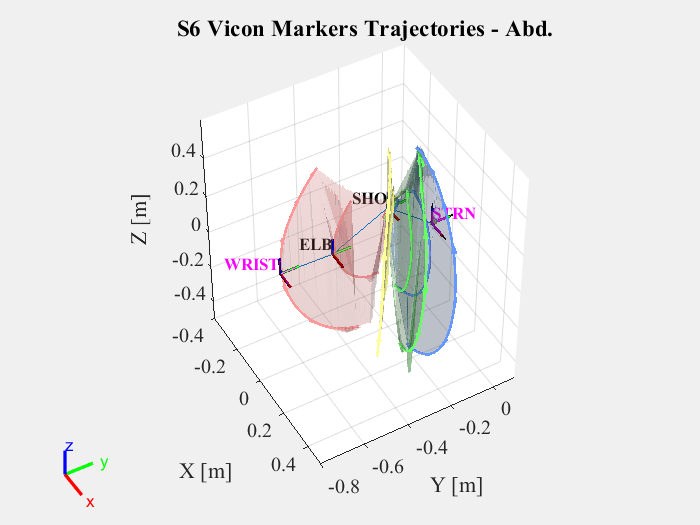

colormap(cmap);

% Set the position of the axes to make room for the legend on the left
ax = gca;
ax.FontName = font_name; % Set font name
ax.FontSize = font_size; % Set font size

title('S6 Vicon Markers Trajectories - Abd.', 'FontName', font_name, 'FontSize', 14);
xlim([-0.4 0.5]); % Limiti per l'asse X
zlim([-0.5 0.6]);
ylim([-0.8 0.1]);

set(gcf, 'GraphicsSmoothing', 'on');  % Abilita l'anti-aliasing

% Salva il grafico come file SVG con dimensioni specifiche
filename = 'S6_abd.svg';
print(gcf, filename, '-dsvg', '-r600');
hold off;

% Function to process abduction data (same as before)

function [x_translated, y_translated, z_translated] = process_abduction_data(filename)
    data = readmatrix(filename);
    coordinate_m = data(6:end/2.7, 3:26) / 1000; % Convert from mm to m

    % Extract x, y, z coordinates
    x = coordinate_m(:, 1:3:end);
    y = coordinate_m(:, 2:3:end);
    z = coordinate_m(:, 3:3:end);

    % Calculate averages for ELB
    x_ELB = (x(:, 3) + x(:, 4)) / 2; % Average between ELB1 and ELB2
    y_ELB = (y(:, 3) + y(:, 4)) / 2;
    z_ELB = (z(:, 3) + z(:, 4)) / 2;

    % Calculate averages for WRIST
    x_WRIST = (x(:, 7) + x(:, 8)) / 2; % Average between WRIST1 e WRIST2
    y_WRIST = (y(:, 7) + y(:, 8)) / 2;
    z_WRIST = (z(:, 7) + z(:, 8)) / 2;

    % Create a new matrix of coordinates with STRN, SHO, ELB, WRIST
    x_selected = [x(:, 1), x(:, 2), x_ELB, x_WRIST];
    y_selected = [y(:, 1), y(:, 2), y_ELB, y_WRIST];
    z_selected = [z(:, 1), z(:, 2), z_ELB, z_WRIST];

    % Translate coordinates relative to the origin of the base frame (STRN)
    x_translated = x_selected - x_selected(1, 1);
    y_translated = y_selected - y_selected(1, 1);
    z_translated = z_selected - z_selected(1, 1);
end
